# Figure 5: The sparse network shows mix attractors depending on the sparseness.

### FIG A: $s = 0.3$

### Pannel a: bifurcation diagram  Amplitude VS w1

Export figure setup: 6 - 4

clear; clc;
s = 0.3;
fig_size = 40;
inner_plot = false;
top_axis = true;

ring_file = fullfile(read_output_dir(), "Fig4\amp_conf_s=0dot3_Ring.mat");
net_file = fullfile(read_output_dir(), "Fig4\amp_conf_s=0dot3.mat");

Amplitude_diagram(s, ring_file, net_file, fig_size, inner_plot, top_axis)

### Pannel b: display the bump amplitude of certain initial condition ($\eta$) over quasi-all environment

4.5 - 3

fig_size = 80; 

load(ring_file, "amplitude_T", "etas_seq")
pos = find(amplitude_T(1, :) >= 0.5, 1,  "last");
eta_cap = etas_seq(1, pos);
display_bump_amp_env(s, eta_cap, fig_size)

### Pannel c: display the bump profile for some initial condition and some weight matrix

4.5 - 3

P = 0.3; D = 0.3;
seed_base = [1987, 1991, 1997, 2018, 2022];
seed_seq = [seed_base, 2*seed_base];
seed = seed_seq(2); eta = 26;
visualized_etas = [0, 1, 2, eta];

display_cross_bump_profile(P, D, s, seed, eta, visualized_etas, fig_size)

### FIG B: $s = 0.5$

### Pannel a: bifurcation diagram  Amplitude VS w1

Export figure setup: 10.5-7

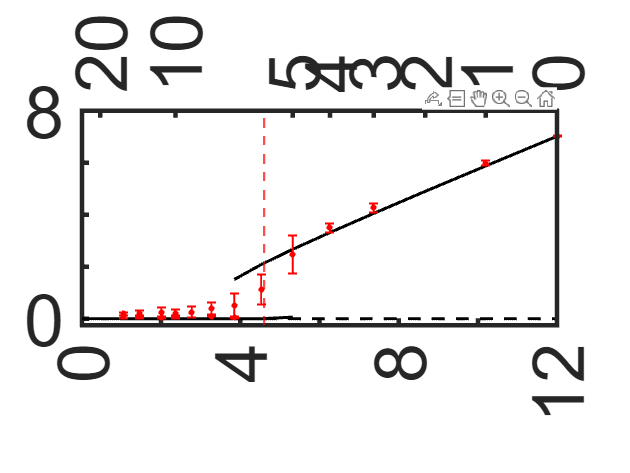

clear; clc;
s = 0.5;
fig_size = 40;
inner_plot = false;
top_axis = true;

ring_file = fullfile(read_output_dir(), "Fig4\amp_conf_s=0dot5_Ring.mat");
net_file = fullfile(read_output_dir(), "Fig4\amp_conf_s=0dot5.mat");

Amplitude_diagram(s, ring_file, net_file, fig_size, inner_plot, top_axis)

### Pannel b: display the bump amplitude of certain initial condition ($\eta$) over quasi-all environment

    "eta = 1, w1 = 10.2"



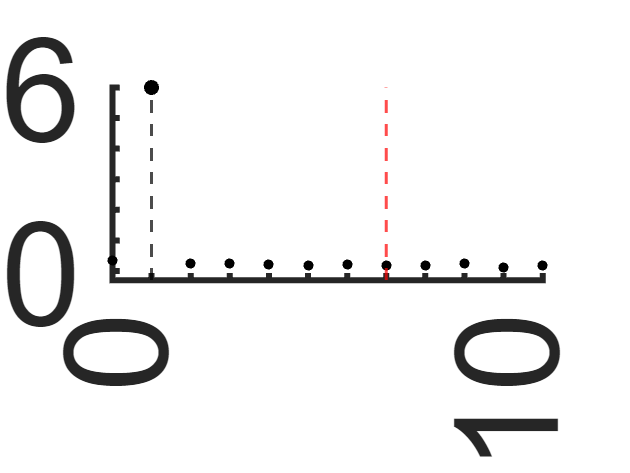

    "eta = 4, w1 = 6.2641"



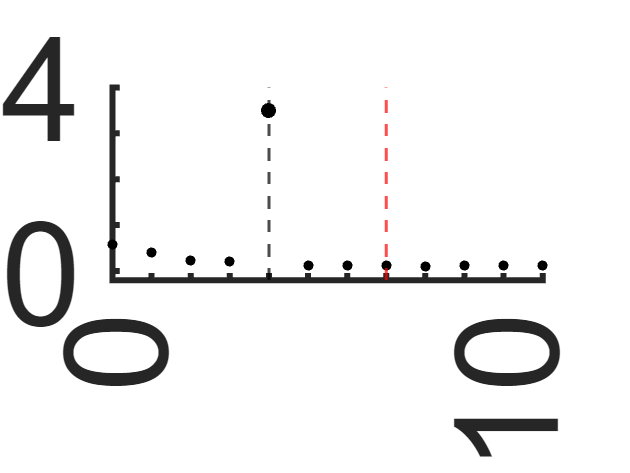

    "eta = 5, w1 = 5.3245"



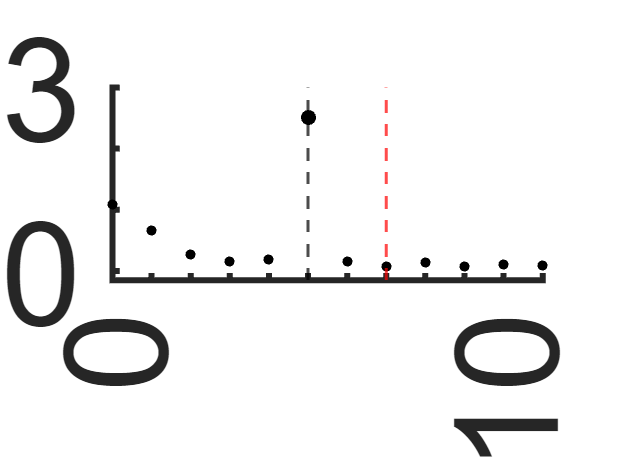

    "eta = 6, w1 = 4.5258"



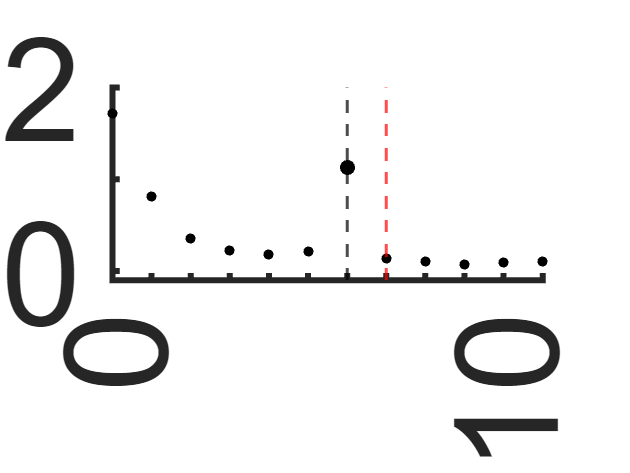

P = 0.3; D = 0.3;
fig_size = 80;
load(ring_file, "amplitude_T", "etas_seq")
pos = find(amplitude_T(1, :) >= 0.5, 1,  "last");
eta_cap = etas_seq(1, pos);
display_bump_amp_env(s, eta_cap, fig_size)

### Pannel c: display the bump profile for some initial condition and some weight matrix

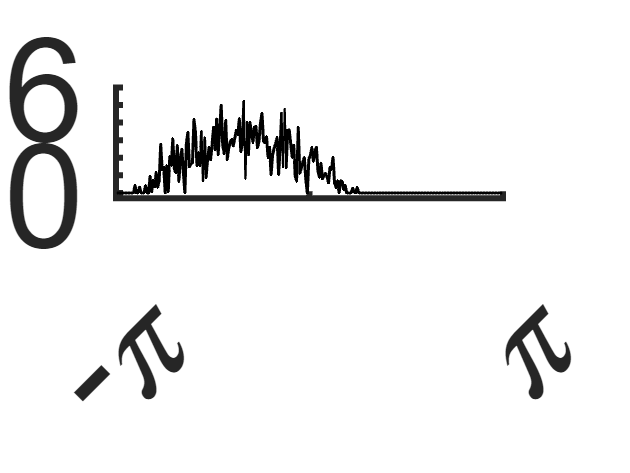

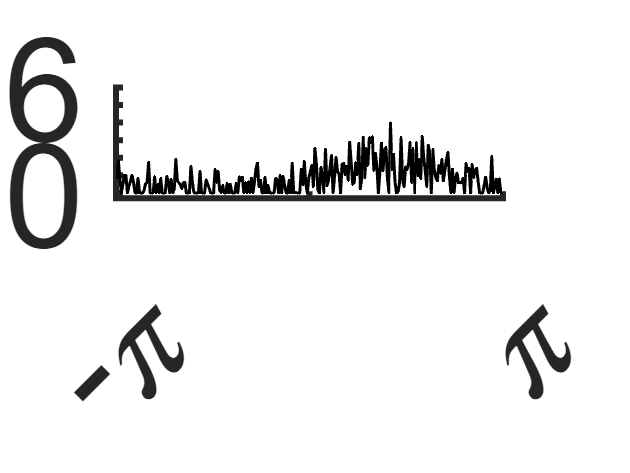

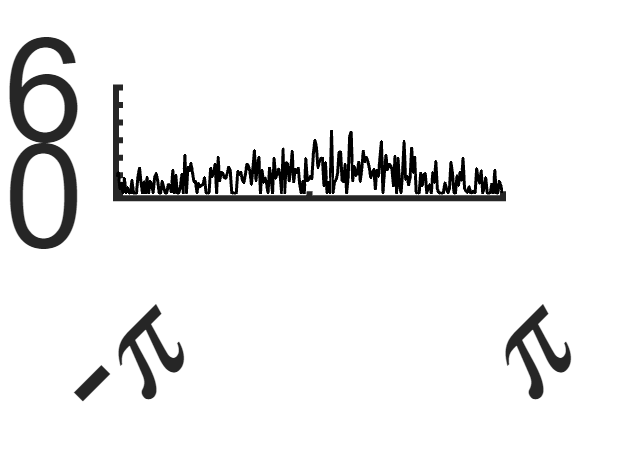

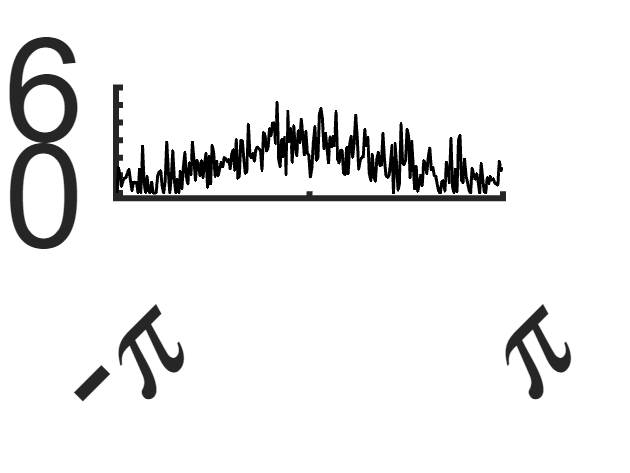

seed_base = [1987, 1991, 1997, 2018, 2022];
seed_seq = [seed_base, 2*seed_base];
seed = seed_seq(2); eta = 6;
visualized_etas = [0, 1, 2, eta];

display_cross_bump_profile(P, D, s, seed, eta, visualized_etas, fig_size)

## Auxiliar function

function Amplitude_diagram(s, ring_file, net_file, fig_size, inner_plot, top_axis)
    
    if nargin < 4
        fig_size = 80;
        inner_plot = false;
        top_axis = false;
    end
    
    if nargin < 5
        inner_plot = false;
        top_axis = false;
    end
    
    load(ring_file)
    
    figure
    t = tiledlayout(1,1);
    ax1 = axes(t);
    plot(ax1, w1s, mean_flat, "k-", "LineWidth", 2)
    hold on
    plot(ax1, w1s, mean_bump, "k-", "LineWidth", 2)

    
    [w1_crit, w1_ring] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track);
    % extend stable line
    w1_stable = 0:0.01:(min(w1s)+0.01);
    stable_part = zeros(1, length(w1_stable));
    w1_unstable = w1_crit:0.01:max(w1s);
    unstable_part = zeros(1, length(w1_unstable));
    
    plot(ax1, w1_stable, stable_part,  "k-", "LineWidth", 2);
    plot(ax1, w1_unstable, unstable_part, "k--", "LineWidth", 2)
    
    
    % load network
    load(net_file)
    flat_ind = var_flat == 0;
    w1s_flat_strange = w1s(flat_ind);
    mean_flat_strange = mean_flat(flat_ind);
    mean_flat(flat_ind) = nan;
    var_flat(flat_ind) = nan;
    
    bump_ind = var_bump == 0;
    w1s_bump_strange = w1s(bump_ind);
    mean_bump_strange = mean_bump(bump_ind);
    mean_bump(bump_ind) = nan;
    var_bump(bump_ind) = nan;
    
    errorbar(ax1, w1s, mean_bump, 1.96*sqrt(var_bump), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
    errorbar(ax1, w1s, mean_flat, 1.96*sqrt(var_flat), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
    if sum(flat_ind) > 0 
        plot(ax1, w1s_flat_strange, mean_flat_strange, "r*", "LineWidth", 1)
    end
    if sum(bump_ind) > 0
        plot(ax1, w1s_bump_strange, mean_bump_strange, "r*", "LineWidth", 1)
    end
    
    hold off
    xline(w1_crit, "r--", "LineWidth", 1.5)
    xlim([0, 12])
    xticks(0:2:12)
    xticklabels([0,  "", 4, "", 8, "", 12])
    
    ylim([-0.25, 8])
    yticks([0, 2, 4, 6, 8])
    yticklabels([0, "", "", "", 8])
    fig_config(fig_size)
    set(gca, 'LineWidth', 3)

    if inner_plot
        axes('Position',[.6 .2 .27 .20])
        plot(w1_backward(amp_backward <= 0.5), amp_backward(amp_backward <= 0.5), "k-", "LineWidth", 2)
        hold on
        plot(w1_backward(amp_backward > 0.5), amp_backward(amp_backward > 0.5), "k-", "LineWidth", 2)
        plot(w1_forward(amp_forward <= 0.5), amp_forward(amp_forward <= 0.5), "k-", "LineWidth", 2)
        plot(w1_forward(amp_forward > 0.5), amp_forward(amp_forward > 0.5), "k-", "LineWidth", 2)
        errorbar(w1s_network, mean_bump, 1.96*sqrt(var_bump), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
        errorbar(w1s_network, mean_flat, 1.96*sqrt(var_flat), "r.", "LineStyle","none", "MarkerSize", 12, "LineWidth", 1.2)
        xline(w1_crit, "--k", "LineWidth", 2)
        hold off
        box off
        xlim([2, 6])
        xticks(2:2:6)
        xticklabels([2, "",  6])
        ylim([-0.5, 4])
        yticks([0, 2, 4, 6])
        yticklabels([0, "", 4])
        set(gca, 'fontsize', fig_size * 1.2 )
        set(gca, 'LineWidth', 3)
    end
    
    if top_axis
        
        if s == 0.2
            idx = [0, 10, 20, 30, 50, 80];
        elseif s == 0.3
            idx = [0, 5, 10, 20, 40];
        elseif s == 0.5
            idx = [0:5, 10, 20];
        end
        
        etas_axis = flip(idx);
        f = @(x, y, k, Sparsity) 2*x*y./(x+y)*(1-Sparsity^2*(x+y)).^k;
        w1s_axis = w_max * f(P, D, etas_axis, s);
        
        ax2 = axes(t);
        ax2.XAxisLocation = 'top';
        ax2.YAxisLocation = 'right';
        %ax2.YAxis.Visible = 'off';
        ax2.XLim = [0, max(w1s_axis)];
        ax2.XTick = [0, w1s_axis];
        ax2.XTickLabel = ["", etas_axis];
        ax2.Color = 'none';
        ax1.Box = "off";
        %ax2.Box = 'off';
        set(gca, 'fontsize', fig_size*1.2)
        set(gca, 'LineWidth', 3)
        set(gca,'ytick',[])
    end
end

function [w1_crit, w1_crit_ring] = find_w1_crit(P, D, M, s, w0, w_max, I0, n_ca3_per_track)
    r0 = (1 - 2*w0*I0 - sqrt(1 - 4*w0*I0)) ./ (2*w0.^2);
    w1_crit_ring = 1 /(w0*r0+I0);
    
    is_stack = true;
    eta = 0;
    w1_aux = 999;
    while w1_aux > w1_crit_ring
        [~, ~, ~, amp, A, ~, C] = Compute_mean_variance(P, D, eta, is_stack, M, s, nan, w0, w_max);
        w1_aux = amp + sqrt(A + C/2) * sqrt(2*pi/(n_ca3_per_track));
        
        eta = eta + 0.1;
    end

    f = @(P, D, eta, s) 2*P*D./(P+D)*(1-s^2*(P+D)).^eta;
    w1_crit = w_max * f(P, D, eta, s);
end

function FR_env_plot(FR, Env_track, eta, phase)
    env_id = Env_track(:, end - eta);
    Selected_FR = FR(env_id);
    Selected_FR_mean = grpstats(Selected_FR, phase, {'mean'});
    plot(unique(phase), Selected_FR_mean, "-", "LineWidth",2);
end

function display_bump_amp_env(s, eta_cap, fig_size)
    file_dir = read_output_dir();
    load_file = "Fig4\Amp_cross_s=" + strrep(string(s), ".", "dot") + ".mat";
    
    load(fullfile(file_dir, load_file));
    
    for i = 1:length(desired_w1s)
        mean_i = mean_bump_amp{i};
        var_i = var_bump_amp{i};
        
        eta = which_eta(i);
        w1 = which_w1(i);
        
        y_max = ceil(max(mean_i));
        
        display("eta = " + eta + ", w1 = " + w1)
        figure
        plot(etas, mean_i, "k.", "MarkerSize", 20)
        hold on
        plot(eta, mean_i(etas == eta), "k.", MarkerSize = 30)
        hold off
        xline(eta, "k--",  "LineWidth", 2)
        xline(eta_cap, "r--", "LineWidth", 2)
        box off
        axis tight
        fig_config(fig_size)
        if s == 0.2
            xticks(0:10:70)
            xticklabels([0, "", "", "", "", "", "",  70]) 
        elseif s == 0.5
            xticks(0:1:11)
            xticklabels([0, repelem("", 9), 10, ""])
        elseif s == 0.3
            xticks([0:5:30. 32])
            xticklabels([0, repelem("", 5), 30, ""])
        end
        ylim([-y_max*0.05, y_max])
        yticks(0:y_max)
        yticklabels([0, repelem("", 1, y_max -1), y_max])
    end
end

function list_files = look_files_by_pattern(dir_name, patterns)    
    all_files = dir(dir_name);
    list_files = {all_files.name};
    for pattern = patterns
        list_files = list_files(contains(list_files, pattern));  
    end
end

function display_cross_bump_profile(P, D, s, seed, eta, visualized_etas, fig_size)
    file_dir = read_output_dir() + "\P=" + strrep(string(P), ".", "dot") + ...
            "D=" + strrep(string(D), ".", "dot");
    
    file = look_files_by_pattern(file_dir, ["FR", "s=" + strrep(string(s), ".", "dot"), string(seed)]);
    load(fullfile(file_dir, file))
    
    indice = etas_seq(1, :) == eta;
    FR_complete = FR_total{1};
    FR_complete = FR_complete(indice, :);
    
    FR_cells = cell(length(visualized_etas), 1);
    
    for i = 1:length(visualized_etas)
        eta_i = visualized_etas(i);
        Env_ind = Env_track(:, end - eta_i);
        FR_Env = FR_complete(Env_ind);
        aux = grpstats(FR_Env, phase, "mean");
        FR_cells{i} = aux';
    end
    FR_cells = cell2mat(FR_cells);
    ymax = ceil(max(FR_cells(:)));
    
    for i = 1:length(visualized_etas)
        figure
        FR_mean = FR_cells(i, :);
        %plot(phase, FR_Env,  ".", "MarkerSize", 20)
        %hold on
        plot(unique(phase), FR_mean, "k-", "LineWidth", 2)
        %hold off
        xlim([-pi, pi])
        xticks([-pi, 0, pi])
        xticklabels(["-\pi", "", "\pi"])
        ylim([-ymax*0.05, ymax])
        yticks(0:1:ymax)
        yticklabels([0, repelem("", 1, ymax -1), ymax])
        fig_config(fig_size)
        box off
    end
end